Спектр отрезка синусоиды

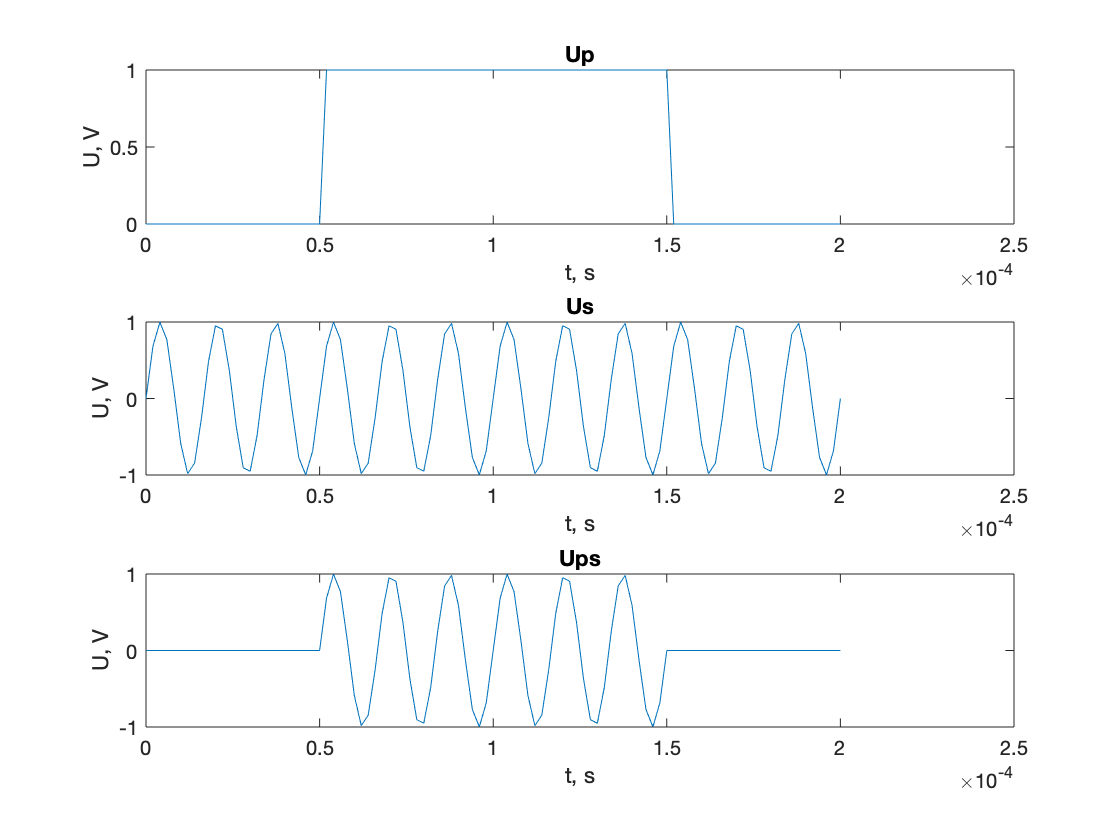

% Шаг дискретизации, в секундах
dt = 0.000002;

% Параметры генератора импульсов
% Задержка начала импульса (Td), в секундах
pulseDelay = 0.00005; 
% Длительность импульса (PW), в секундах
pulseDuration = 0.0001;
% Период следования импульсов, в секундах
pulsePeriod = 0.0002;
% Амплитуда импульса, в вольтах
pulseAmp = 1;

% Параметры генератора гармонического сигнала
% Частота, в герцах
sinF = 60000;
% Амплитуда, в вольтах
sinAmp = 1;

% Длительность измерений, в секундах
RunToTime = 2*pulseDuration;

t=[0:dt:RunToTime]; 

rectPulseGenerator = rectPulse(pulseDelay, pulseDuration, pulseAmp);
periodicPulseGenerator = periodPulse(rectPulseGenerator, pulsePeriod);
sinGenerator = sinSignal(sinF, pulseAmp);

% получение отсчетов сигналов Up, Us, и Ups
Up = periodicPulseGenerator(t);
Us = sinGenerator(t);
Ups = Up.*Us;

% временные диаграммы моделируемых сигналов
figure('name', 'Signals in time domain');
subplot(3,1,1); plot(t,Up); title('Up'); xlabel('t, s'); ylabel('U, V');
subplot(3,1,2); plot(t,Us); title('Us'); xlabel('t, s'); ylabel('U, V');
subplot(3,1,3); plot(t,Ups); title('Ups'); xlabel('t, s'); ylabel('U, V');

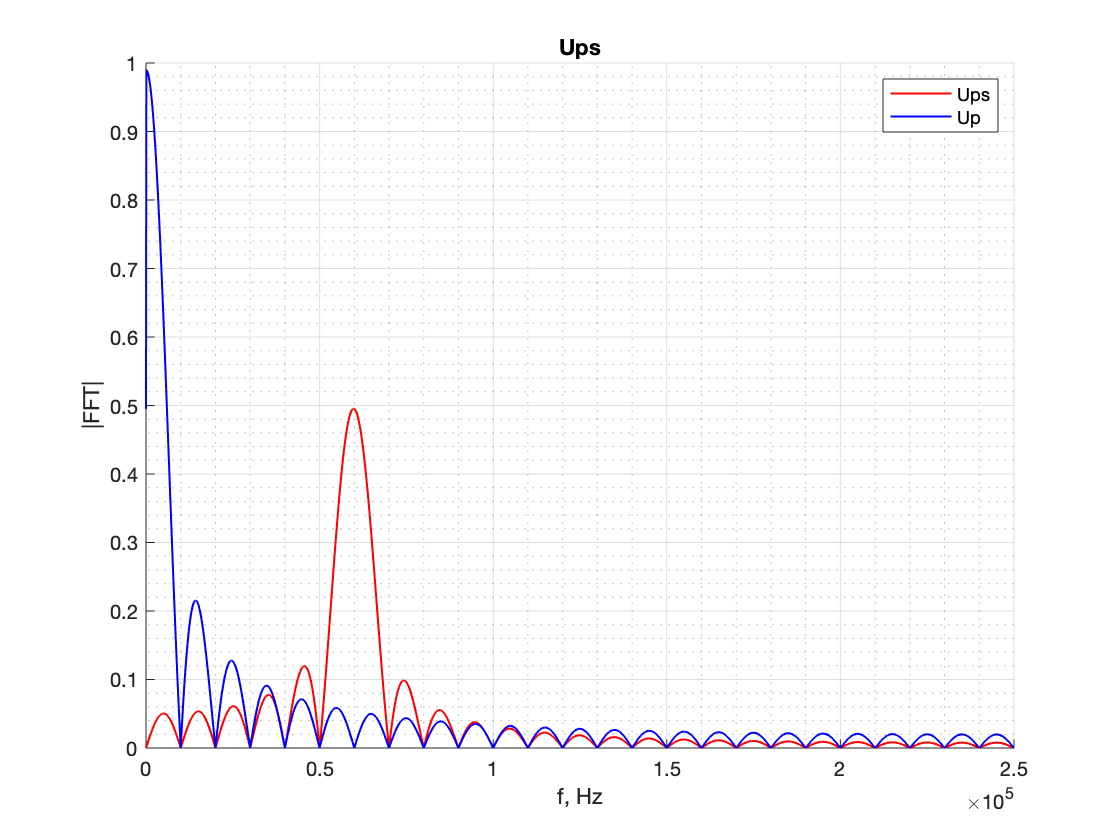


% вычисление БПФ для Up и Ups и построение графика модуля спектра
[fftAmp, fftF] = analyzeFFT(Ups, dt);
[fftAmp1, fftF1] = analyzeFFT(Up, dt);

figure('name', '|FFT|(interpolated)'); 
%stem(shiftedF, abs(shiftedOut(1:2^(N))));
grid on;
grid minor;
hold on;
plot(fftF, abs(fftAmp), 'r', 'LineWidth',1);
plot(fftF1, abs(fftAmp1), 'b', 'LineWidth',1);
hold off;
xlabel('f, Hz'); ylabel('|FFT|');
title('Ups');
legend('Ups','Up');

Пачка импульсов

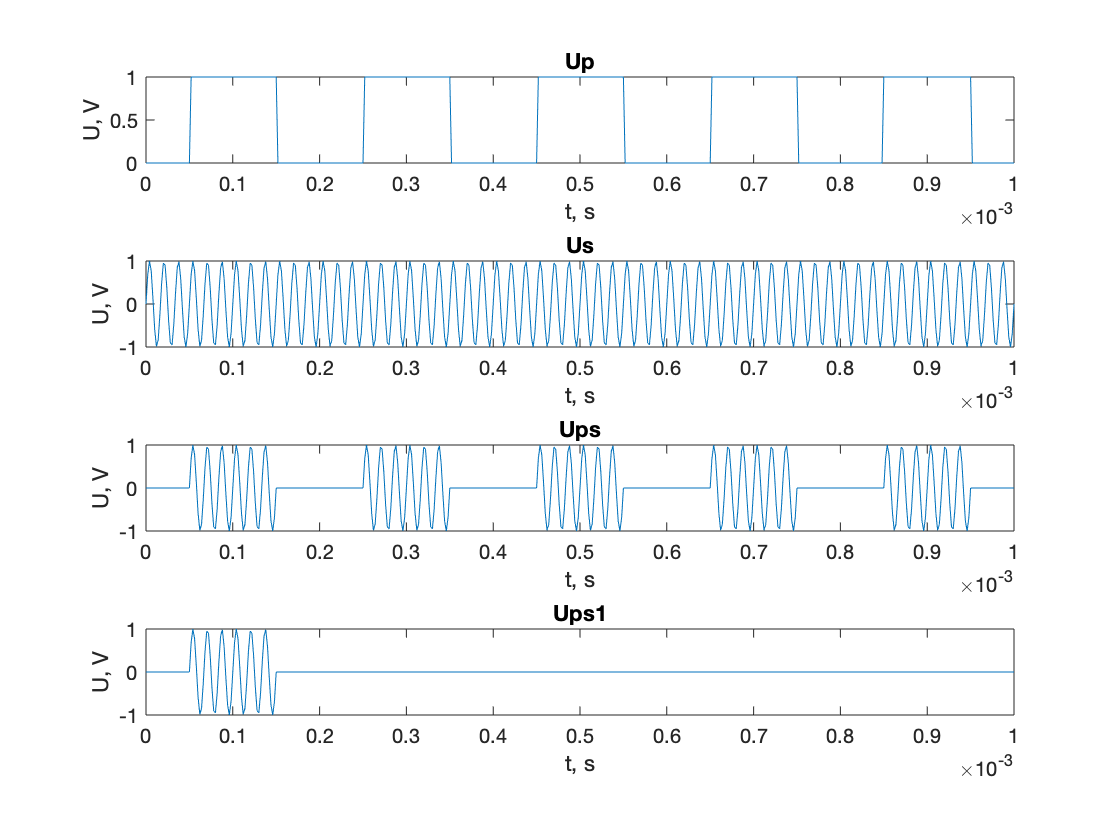

% Шаг дискретизации, в секундах
dt = 0.000002;

% Параметры генератора импульсов
% Задержка начала импульса (Td), в секундах
pulseDelay = 0.00005; 
% Длительность импульса (PW), в секундах
pulseDuration = 0.0001;
% Период следования импульсов, в секундах
pulsePeriod = 0.0002;
% Амплитуда импульса, в вольтах
pulseAmp = 1;

% Параметры генератора гармонического сигнала
% Частота, в герцах
sinF = 60000;
% Амплитуда, в вольтах
sinAmp = 1;

% Длительность измерений, в секундах
RunToTime = 5*pulsePeriod; % два импульса

% Отсчеты времени, в которых вычисляются значения сигналов
% от 0 до RunToTime секунд с шагом dt
t=[0:dt:RunToTime]; 

rectPulseGenerator = rectPulse(pulseDelay, pulseDuration, pulseAmp);
periodicPulseGenerator = periodPulse(rectPulseGenerator, pulsePeriod);
sinGenerator = sinSignal(sinF, pulseAmp);

% получение отсчетов сигналов Up, Us, и Ups
Up = periodicPulseGenerator(t);
Us = sinGenerator(t);

Ups = Up.*Us;

% отсчеты сигнала одного периода Ups
Ups1 = rectPulseGenerator(t).*sinGenerator(t);

% временные диаграммы моделируемых сигналов
figure('name', 'Time domain');
subplot(4,1,1); plot(t,Up); title('Up'); xlabel('t, s'); ylabel('U, V');
subplot(4,1,2); plot(t,Us); title('Us'); xlabel('t, s'); ylabel('U, V');
subplot(4,1,3); plot(t,Ups); title('Ups'); xlabel('t, s'); ylabel('U, V');
subplot(4,1,4); plot(t,Ups1); title('Ups1'); xlabel('t, s'); ylabel('U, V');

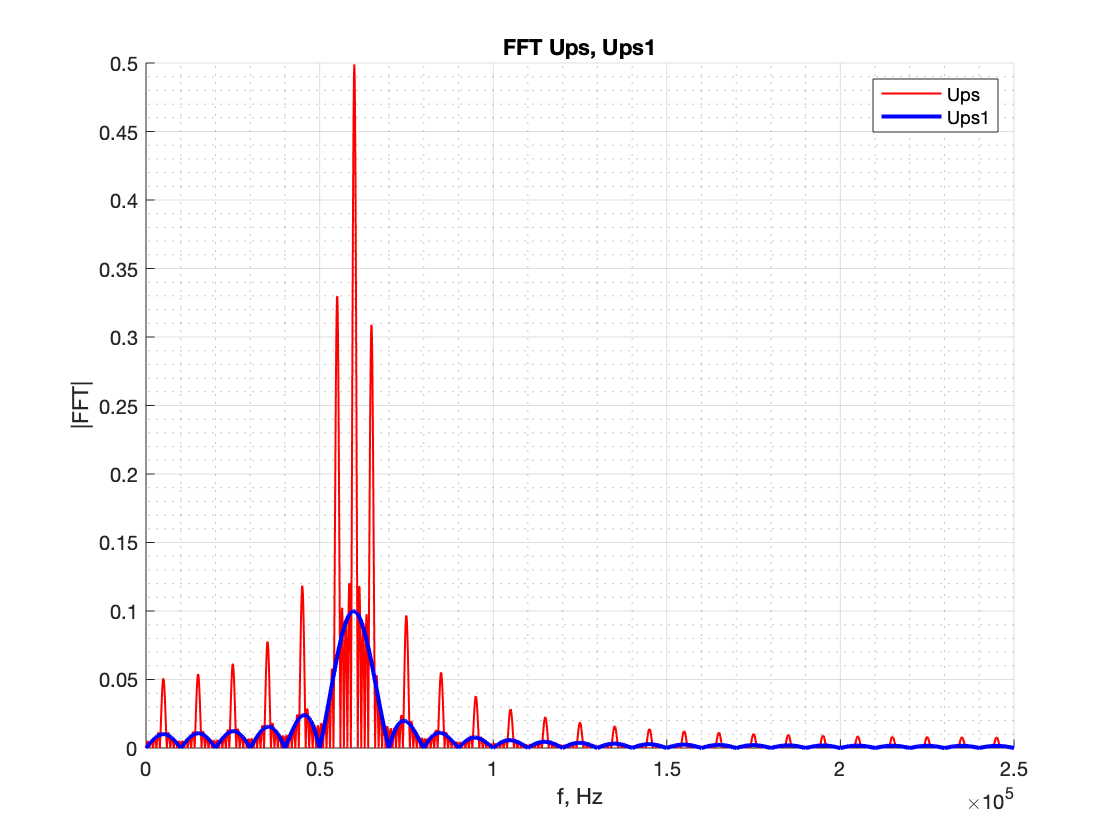


% вычисление БПФ для Ups и Ups1 и построение графика модуля спектра
[fftAmp, fftF] = analyzeFFT(Ups, dt);
[fftAmp1, fftF1] = analyzeFFT(Ups1, dt);

figure('name', '|FFT|'); 
%stem(shiftedF, abs(shiftedOut(1:2^(N))));
grid on;
grid minor;
hold on;
plot(fftF, abs(fftAmp), 'r', 'LineWidth',1);
plot(fftF1, abs(fftAmp1), 'b', 'LineWidth',2);
hold off;
xlabel('f, Hz'); ylabel('|FFT|');
title('FFT Ups, Ups1');
legend('Ups','Ups1');

Длительность импульса и ширина спектра

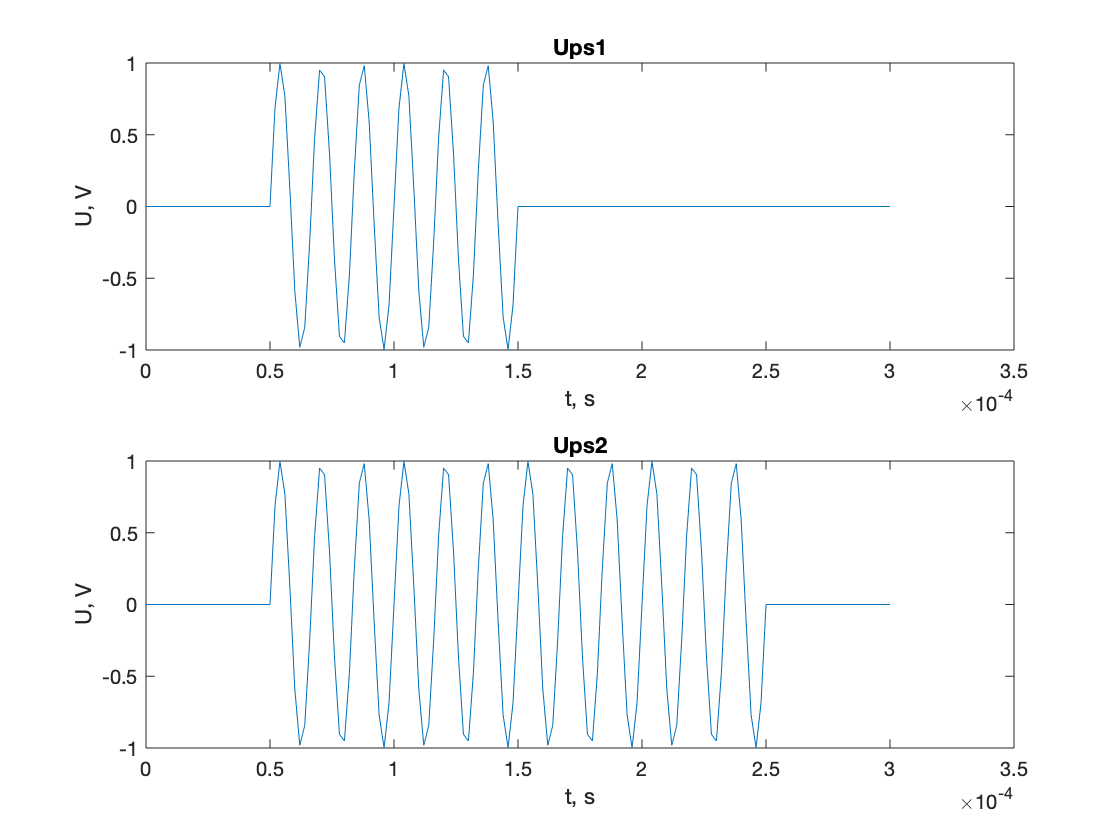

% Шаг дискретизации, в секундах
dt = 0.000002;

% Параметры генератора импульсов
% Задержка начала импульса (Td), в секундах
pulseDelay = 0.00005; 
% Длительность импульса (PW), в секундах
pulseDuration = 0.0001;
% Период следования импульсов, в секундах
pulsePeriod = 0.0002;
% Амплитуда импульса, в вольтах
pulseAmp = 1;

% Параметры генератора гармонического сигнала
% Частота, в герцах
sinF = 60000;
% Амплитуда, в вольтах
sinAmp = 1;

% Ниже описана процедура моделирования

% Длительность измерений, в секундах
RunToTime = 3*pulseDuration;

% Отсчеты времени, в которых вычисляются значения сигналов
% от 0 до RunToTime секунд с шагом dt
t=[0:dt:RunToTime]; 

rectPulseGenerator1 = rectPulse(pulseDelay, pulseDuration, sinAmp);
rectPulseGenerator2 = rectPulse(pulseDelay, 2*pulseDuration, sinAmp);

sinGenerator = sinSignal(sinF, pulseAmp);

Ups1 = rectPulseGenerator1(t).*sinGenerator(t);
Ups2 = rectPulseGenerator2(t).*sinGenerator(t);

% временные диаграммы моделируемых сигналов
figure('name', 'Time domain');
subplot(2,1,1); plot(t,Ups1); title('Ups1'); xlabel('t, s'); ylabel('U, V');
subplot(2,1,2); plot(t,Ups2); title('Ups2'); xlabel('t, s'); ylabel('U, V');

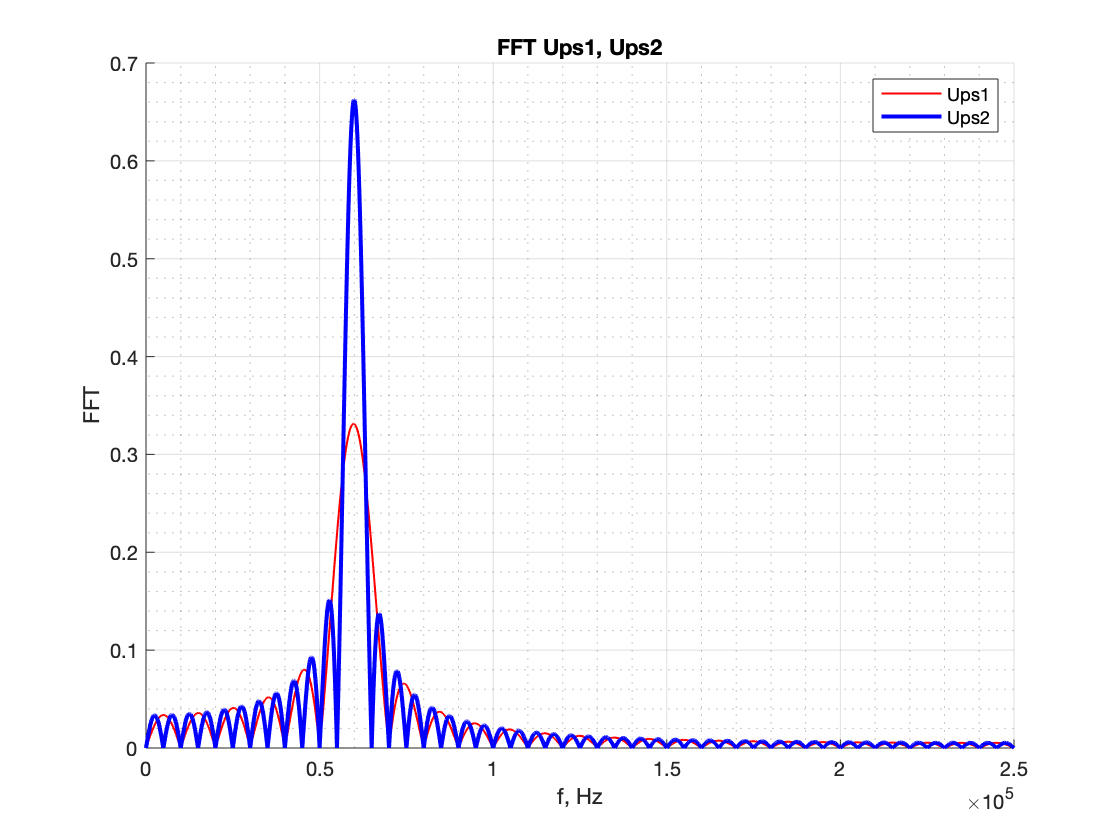


% вычисление БПФ для Ups1 и Ups2 и построение графика модуля спектра
[fftAmp1, fftF1] = analyzeFFT(Ups1, dt);
[fftAmp2, fftF2] = analyzeFFT(Ups2, dt);

figure('name', 'FFT'); 
%stem(shiftedF, abs(shiftedOut(1:2^(N))));
grid on;
grid minor;
hold on;
plot(fftF1, abs(fftAmp1), 'r', 'LineWidth',1);
plot(fftF2, abs(fftAmp2), 'b', 'LineWidth',2);
hold off;
xlabel('f, Hz'); ylabel('FFT');
title('FFT Ups1, Ups2');
legend('Ups1','Ups2');

Треугольный импульс (один генератор)

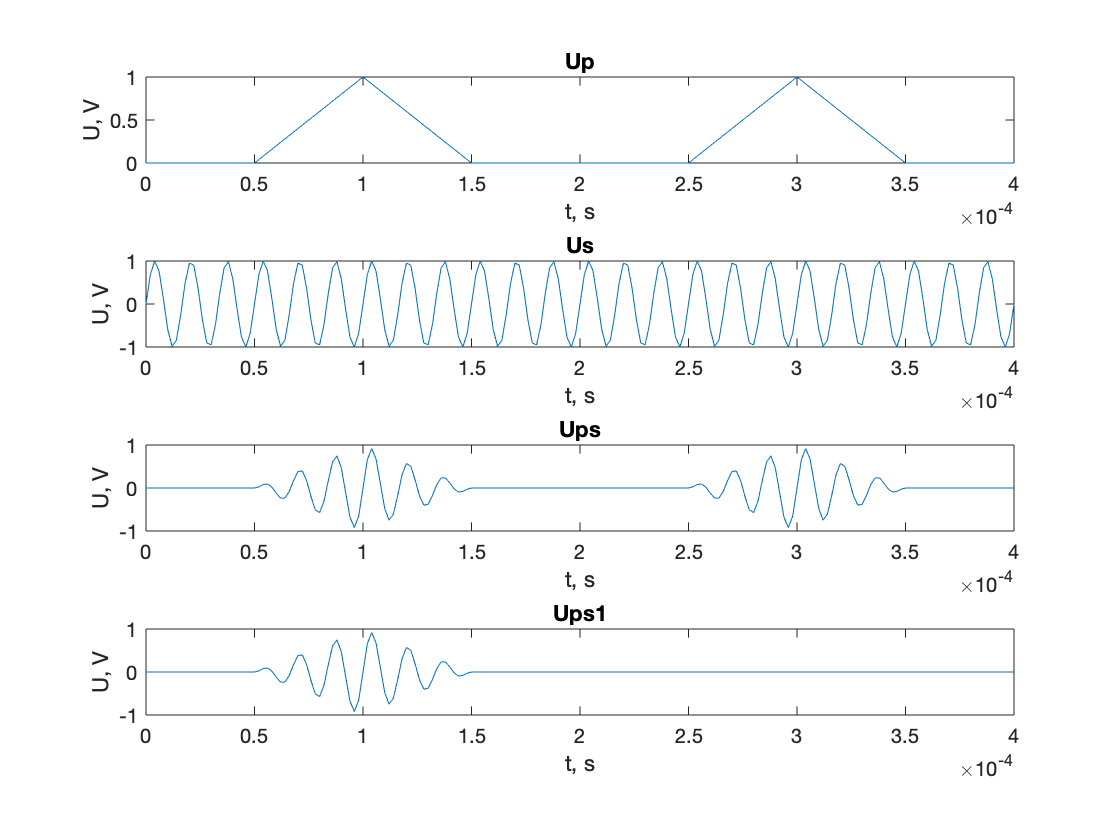


% Шаг дискретизации, в секундах
dt = 0.000002;

% Параметры генератора импульсов
% Задержка начала импульса (Td), в секундах
pulseDelay = 0.00005; 
% Длительность импульса (PW), в секундах
pulseDuration = 0.0001;
% Период следования импульсов, в секундах
pulsePeriod = 0.0002;
% Амплитуда импульса, в вольтах
pulseAmp = 1;

% Параметры генератора гармонического сигнала
% Частота, в герцах
sinF = 60000;
% Амплитуда, в вольтах
sinAmp = 1;

% Ниже описана процедура моделирования

% Длительность измерений, в секундах
RunToTime = 2*pulsePeriod;

% Отсчеты времени, в которых вычисляются значения сигналов
% от 0 до RunToTime секунд с шагом dt
t=[0:dt:RunToTime]; 

trianglePulseGenerator = polyPulse([pulseDelay, 0; pulseDuration/2+pulseDelay, 1; pulseDuration+pulseDelay,0]);
periodicPulseGenerator = periodPulse(trianglePulseGenerator, pulsePeriod);
sinGenerator = sinSignal(sinF, pulseAmp);

% получение отсчетов сигналов Up, Us, и Ups
Up = periodicPulseGenerator(t);
Us = sinGenerator(t);

% чтобы записать произведение отсчетов
% двух сигналов, нужно использовать операцию .*
Ups = Up.*Us;

% отсчеты сигнала одного периода Ups
Ups1 = trianglePulseGenerator(t).*sinGenerator(t);

% временные диаграммы моделируемых сигналов
figure('name', 'Time domain');
subplot(4,1,1); plot(t,Up); title('Up'); xlabel('t, s'); ylabel('U, V');
subplot(4,1,2); plot(t,Us); title('Us'); xlabel('t, s'); ylabel('U, V');
subplot(4,1,3); plot(t,Ups); title('Ups'); xlabel('t, s'); ylabel('U, V');
subplot(4,1,4); plot(t,Ups1); title('Ups1'); xlabel('t, s'); ylabel('U, V');

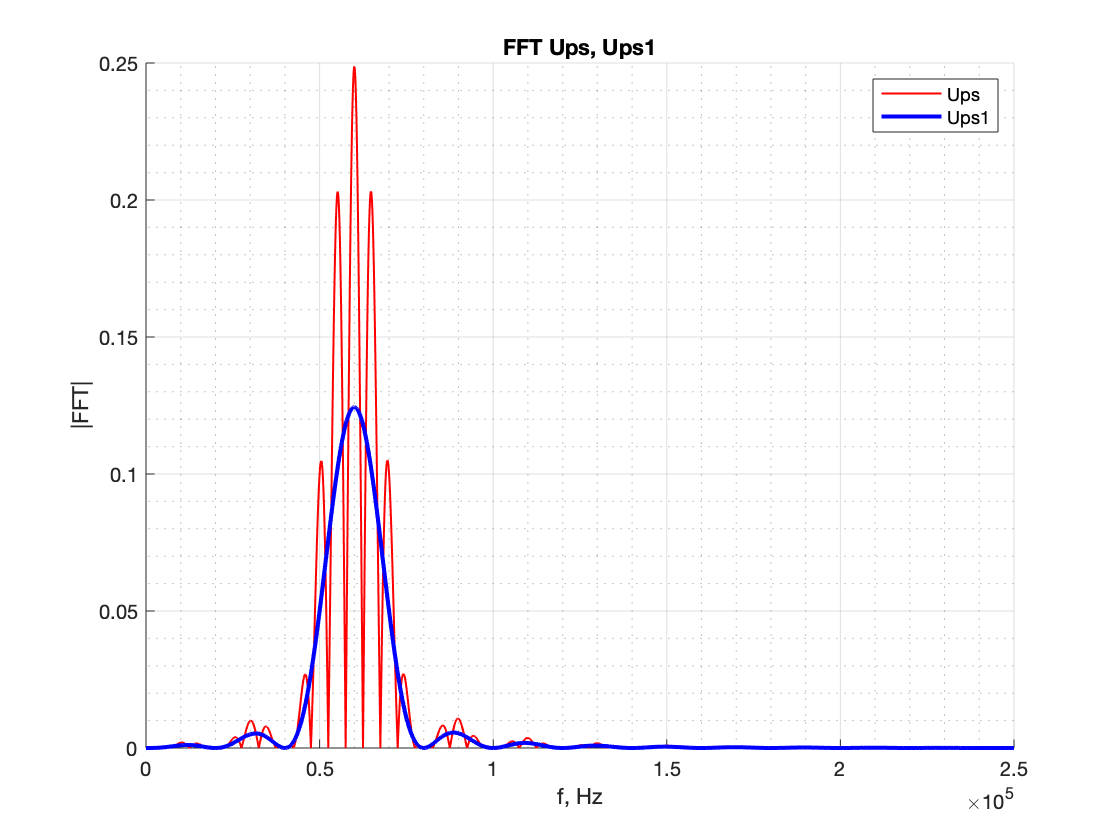


% вычисление БПФ для Ups и Ups1 и построение графика модуля спектра
[fftAmp, fftF] = analyzeFFT(Ups, dt);
[fftAmp1, fftF1] = analyzeFFT(Ups1, dt);

figure('name', '|FFT|'); 
%stem(shiftedF, abs(shiftedOut(1:2^(N))));
grid on;
grid minor;
hold on;
plot(fftF, abs(fftAmp), 'r', 'LineWidth',1);
plot(fftF1, abs(fftAmp1), 'b', 'LineWidth',2);
hold off;
xlabel('f, Hz'); ylabel('|FFT|');
title('FFT Ups, Ups1');
legend('Ups','Ups1');

Треугольный ипмульс (два генератора)

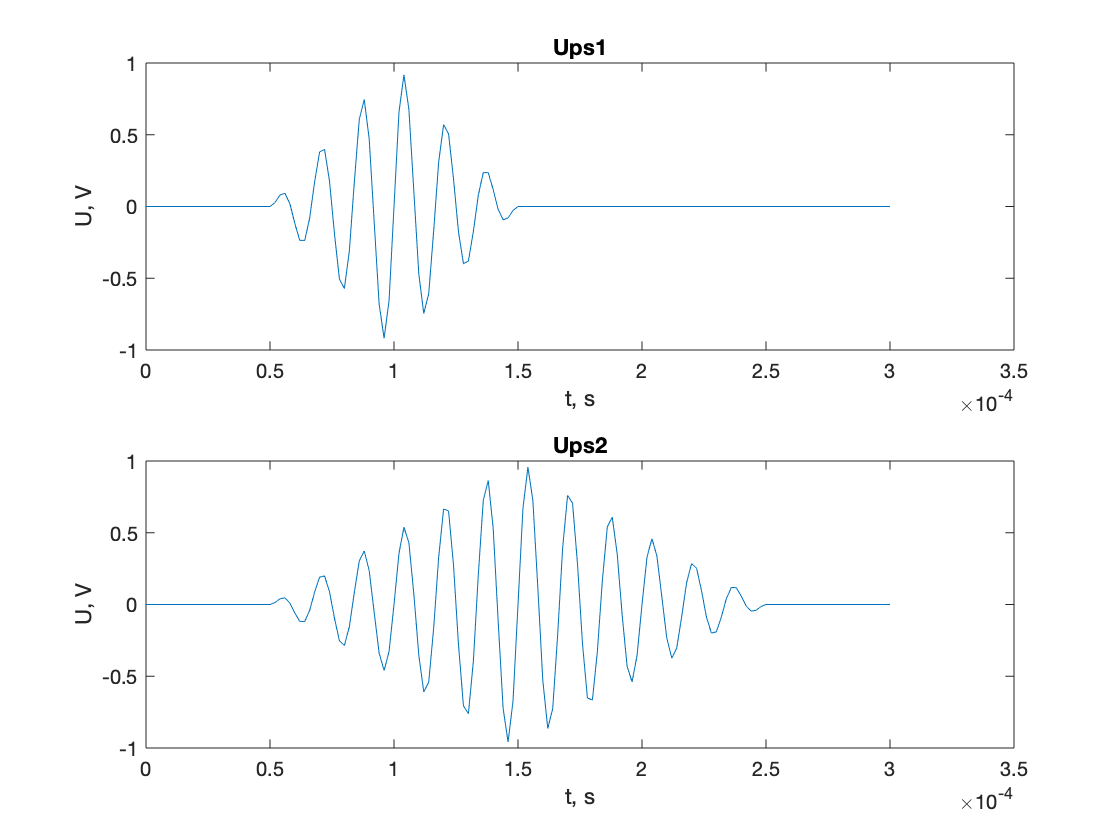

% Шаг дискретизации, в секундах
dt = 0.000002;

% Параметры генератора импульсов
% Задержка начала импульса (Td), в секундах
pulseDelay = 0.00005; 
% Длительность импульса (PW), в секундах
pulseDuration = 0.0001;
% Период следования импульсов, в секундах
pulsePeriod = 0.0002;
% Амплитуда импульса, в вольтах
pulseAmp = 1;

% Параметры генератора гармонического сигнала
% Частота, в герцах
sinF = 60000;
% Амплитуда, в вольтах
sinAmp = 1;

% Ниже описана процедура моделирования

% Длительность измерений, в секундах
RunToTime = 3*pulseDuration;

% Отсчеты времени, в которых вычисляются значения сигналов
% от 0 до RunToTime секунд с шагом dt
t=[0:dt:RunToTime]; 

trianglePulseGenerator1 = polyPulse([pulseDelay, 0; pulseDuration/2+pulseDelay, 1; pulseDuration+pulseDelay,0]);
trianglePulseGenerator2 = polyPulse([pulseDelay, 0; pulseDuration+pulseDelay, 1; 2*pulseDuration+pulseDelay,0]);

sinGenerator = sinSignal(sinF, pulseAmp);

Ups1 = trianglePulseGenerator1(t).*sinGenerator(t);
Ups2 = trianglePulseGenerator2(t).*sinGenerator(t);

% временные диаграммы моделируемых сигналов
figure('name', 'Time domain');
subplot(2,1,1); plot(t,Ups1); title('Ups1'); xlabel('t, s'); ylabel('U, V');
subplot(2,1,2); plot(t,Ups2); title('Ups2'); xlabel('t, s'); ylabel('U, V');

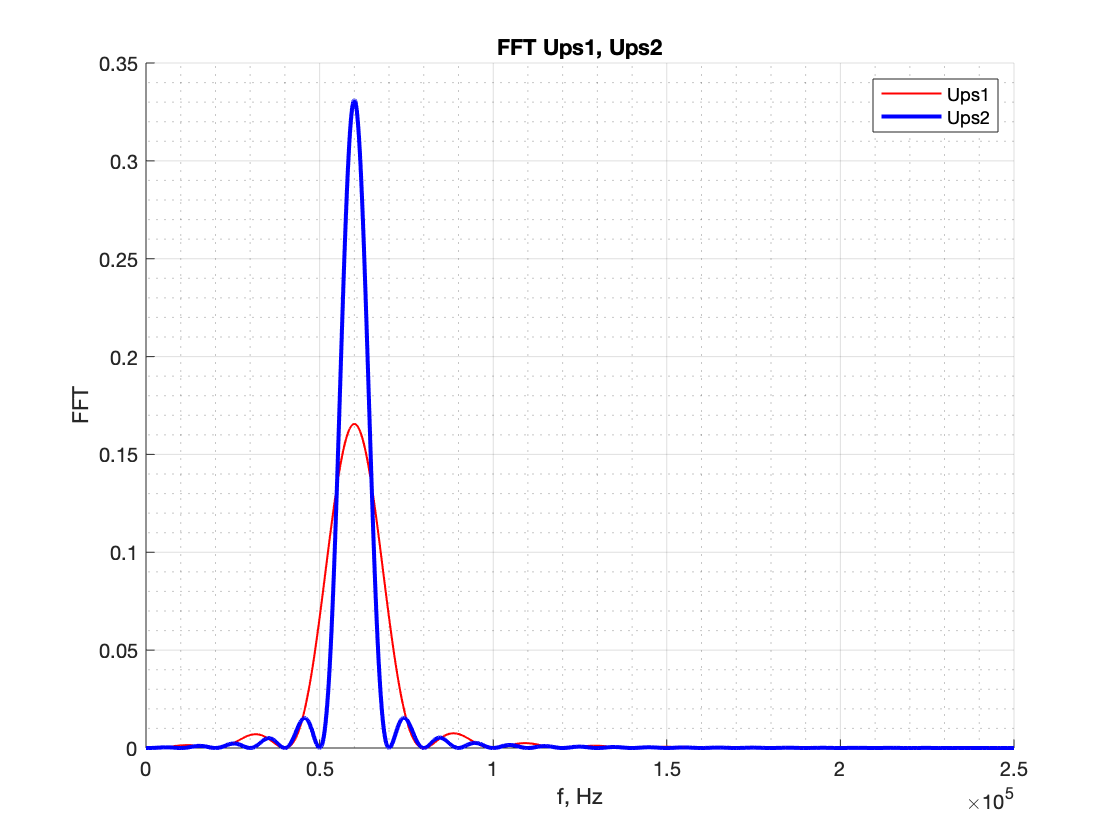


% вычисление БПФ для Ups1 и Ups2 и построение графика модуля спектра
[fftAmp1, fftF1] = analyzeFFT(Ups1, dt);
[fftAmp2, fftF2] = analyzeFFT(Ups2, dt);

figure('name', 'FFT'); 
%stem(shiftedF, abs(shiftedOut(1:2^(N))));
grid on;
grid minor;
hold on;
plot(fftF1, abs(fftAmp1), 'r', 'LineWidth',1);
plot(fftF2, abs(fftAmp2), 'b', 'LineWidth',2);
hold off;
xlabel('f, Hz'); ylabel('FFT');
title('FFT Ups1, Ups2');
legend('Ups1','Ups2');